# Example: Basic Solver for Acoustics in 2D with PML

This live-script features the following:

- how to set up PML in 2D

Refer to `ex_Acoustic1D_basic.mlx `for more explanation on the basic set up.

clear

domain_x = [0,1];
domain_y = [0,1.2];
domain_t = [0,1.1];

%% Computational and output grids
Nx = 161;
Ny = 171;
gsp_P = GridSpace2D( ...
    Grid1DUnifPrimal(domain_x,Nx), ...
    Grid1DUnifPrimal(domain_y,Ny) );
h = gsp_P.h;

% Acoustic medium
medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
[~,~,~,~,cMax] = sampleMedium2D(gsp_P,medium);

% Time grid (computed after medium)
CFL_factor = 0.9;
dt = CFL_factor*(6/7)/(cMax*sqrt(sum(1./gsp_P.h.^2))); %CFL condition for 2-4 FDM
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

% Ouput spatial grid and time points
gsp_out = GridSpace2D( ...
    Grid1DUnifPrimal(domain_x,81), ...
    Grid1DUnifPrimal(domain_y,81));
t_pts_out = linspace(domain_t(1),domain_t(2),51);

% Acoustic source
source = AcousticSource2D( ...
    @(x,y) exp(-((x-0.40)/0.045).^2-((y-0.55)/0.045).^2), ...
    @(t) exp(-((t-0.08)/0.018).^2));

% Initial data
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));


Here we initialize the PML object for our simulation.

Assuming our x domain is the interval $[a,b]$, then $x=a$ and $x=b$ are referred to the **left** and **right** boundaries, respectively.

Assuming our y domain is the interval $[c,d]$, then $y=c$ and $y=d$ are referred to the **bottom** and **top** boundaries, respectively.

The PML widths are relative. For example, `WidthLeft=0.2` is interpreted as a PML width of roughly 20% the width of the computational domain.

There are other parameters one can specify when initializing a PML. Refer to the class definition.

% Initializing PML
pml = PML2D( ...
    WidthLeft=0.15, ...
    WidthRight=0, ...
    WidthBottom=0.15, ...
    WidthTop=0.15);

Here we initialize the acoustic solver that incorporates PML.

solver = AcousticSolver2D_PML( ...
    gsp_P,t_pts, ...
    gsp_out,t_pts_out, ...
    medium,pml, ...
    SpatialOrder=4);

%% Running solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0,Source=source);

Here we visualize the computed pressure field. Note, no reflection from the left boundary, but a reflection at the right boundary.

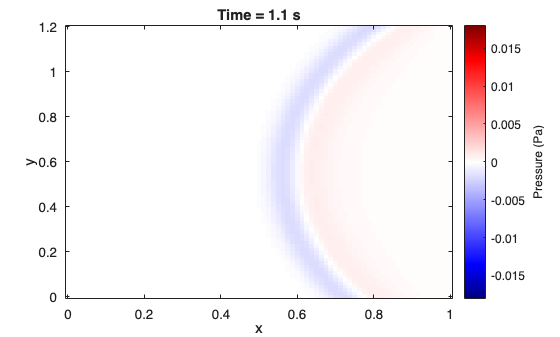

ax = axes(figure(Name="Pressure with PML"));
P.animate(FramePause=0.03,Parent=ax);